# Sistemi Dinamici - Prova parziale 27/10/2023

**Alberto Zurini**

**voto massimo: 4 punti**

Il voto finale sarà costituito dalla somma delle valutazioni conseguite nei due esercizi.

## Esercizio 2

È assegnato il sistema dinamico lineare, stazionario, a tempo discreto, descritto dalle equazioni di stato


$$\left\{ \begin{array}{rcl}
x(k+1) &=& \left[ \begin{array}{ccc}
0 & -2& +1 \\
-1 & 0 & 0 \\
0 & -1 & 0
\end{array}\right] \cdot x(k) +
\left[ \begin{array}{c}
5 \\ 0 \\5
\end{array} \right] \cdot u(k) \\
\\
y(k) &=& \left[ \begin{array}{cc}
-1 & 0 +1
\end{array} \right] \cdot x(k)
\end{array} \right.$$


% Inizializzazione:

clear
close all
clc 
% pulizia del workspace di MATLAB prima di iniziare

rng(4321567); % inizializzo il generatore di numeri casuali

### Domanda 1)

- Determinare gli autovalori del sistema e verificare che il sistema è instabile.

**Suggerimento**: fare buon uso del comando `eig()`

#### Risposta

Inserisci in questa sezione il codice MATLAB richiesto, adeguatamente commentato ed accompagna il codice con una breve descrizione delle scelte fatte, delle motivazioni e di tutto ciò che ritieni possa essere utile a comprendere meglio l'approccio seguito per ottenere il risultato, facendo uso della possibilità di inserire testo, immagini, formule a corredo del codice stesso. 

% inserisci il codice che risolve il problema proposto
% usa dei brevi commenti nel codice, per rendere il codice più leggibile

% matrix description of the system:
A = [0 -2 1
     -1 0 0
     0 -1 0];
B = [5; 0; 5];
C = [-1 0 1];

lambdas = eig(A)

lambdas =     1.6180
   -1.0000
   -0.6180


Having a look at the eigenvalues of the system, we can immediatly notice that at least one of them has a module $\gt 1$, hence the system we are dealing with is unstable.

### **Domanda 2)**

- Determinare i modi di risposta del sistema.

- Determinare uno stato iniziale $\bar x = \big[ \alpha\,,\;\beta\,,\; \gamma \big]^{\top}$ tale da garantire che l'evoluzione libera dello stato a partire da $\bar x$ come stato iniziale non diverga.

**Suggerimento**: sfruttare in modo opportuno il comando `eig()` ed il comando `initial().`

#### Risposta

Inserisci in questa sezione il codice MATLAB richiesto, adeguatamente commentato ed accompagna il codice con una breve descrizione delle scelte fatte, delle motivazioni e di tutto ciò che ritieni possa essere utile a comprendere meglio l'approccio seguito per ottenere il risultato, facendo uso della possibilità di inserire testo, immagini, formule a corredo del codice stesso. 

% inserisci il codice che risolve il problema proposto
% usa dei brevi commenti nel codice, per rendere il codice più leggibile

Since all the eigenvalues are distinct and have no imaginary part, we can calculate the response modes using the following formula:


$$A_k = \lim_{z \to \lambda_k} (z - \lambda_k)(zI - A)^{-1}$$


for each eigenvalue $\lambda_k$

z = sym("z");
k = sym("k");
zIA = z*eye(size(A)) - A;
zIA_inv = inv(zIA);

to_limit1 = (z - lambdas(1))*zIA_inv;
to_limit2 = (z - lambdas(2))*zIA_inv;
to_limit3 = (z - lambdas(3))*zIA_inv;


$$A1 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

A1 = limit(to_limit1, lambdas(1))

$$A2 = \left(\begin{array}{ccc} 1 & 1 & -1\\ 1 & 1 & -1\\ 1 & 1 & -1 \end{array}\right)$$

A2 = limit(to_limit2, lambdas(2))

$$A3 = \left(\begin{array}{ccc} 0 & 0 & 0\\ 0 & 0 & 0\\ 0 & 0 & 0 \end{array}\right)$$

A3 = limit(to_limit3, lambdas(3))

$$Apow = \left(\begin{array}{ccc} {\left(-1\right)}^{k} & {\left(-1\right)}^{k} & -{\left(-1\right)}^{k}\\ {\left(-1\right)}^{k} & {\left(-1\right)}^{k} & -{\left(-1\right)}^{k}\\ {\left(-1\right)}^{k} & {\left(-1\right)}^{k} & -{\left(-1\right)}^{k} \end{array}\right)$$

Apow = lambdas(1)^k * A1 + lambdas(2)^k * A2 + lambdas(3)^k * A3

% Apow_check = A^k

Determinare uno stato iniziale $\bar x = \big[ \alpha\,,\;\beta\,,\; \gamma \big]^{\top}$ tale da garantire che l'evoluzione libera dello stato a partire da $\bar x$ come stato iniziale non diverga.

Let's try the null vector:

x_hat = [0 0 0]';


ans =      0
     0
     0


A * x_hat

This is an equilibrium state.

a = sym("a");
b = sym("b");
c = sym("c");

$$x\_hat2 = \left(\begin{array}{c} \bar{a}\\ \bar{b}\\ \bar{c} \end{array}\right)$$

x_hat2 = [a b c]'

$$ans = \left(\begin{array}{c} \bar{c}-2\,\bar{b}\\ -\bar{a}\\ -\bar{b} \end{array}\right)$$

A * x_hat2

Having a look at those equations, the only vector that satisfies that each row is equal on the two vectors is the null vector.

### Domanda 3)

- Determinare i primi $20$ campioni dell'evoluzione libera dello stato del sistema a partire dallo stato iniziale $\bar x$ .

- Raffigurare il movimento in una figura che contenga 3 grafici distinti, uno per l'evoluzione nel tempo di ciascuna delle componenti del vettore di stato.

- Assumere periodo di campionamento pari a $T_s = 1$ s per la determinazione del movimento libero di stato.

**Suggerimento**: sfruttare in modo opportuno il comando initial`(),` il comando plot`()e subplot().`

#### Risposta

Inserisci in questa sezione il codice MATLAB richiesto, adeguatamente commentato ed accompagna il codice con una breve descrizione delle scelte fatte, delle motivazioni e di tutto ciò che ritieni possa essere utile a comprendere meglio l'approccio seguito per ottenere il risultato, facendo uso della possibilità di inserire testo, immagini, formule a corredo del codice stesso. 

% inserisci il codice che risolve il problema proposto
% usa dei brevi commenti nel codice, per rendere il codice più leggibile

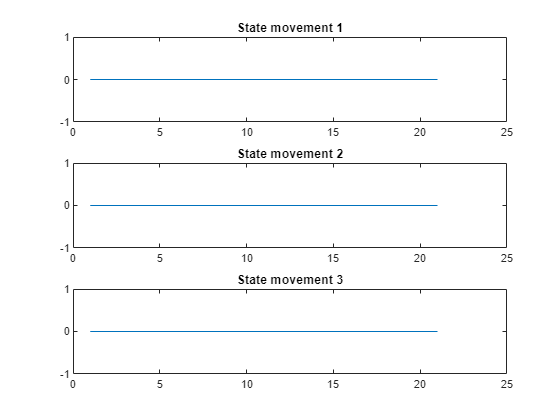

sys = ss(A,B,C,0,1);
[y, ~, x] = initial(sys,x_hat,20);

howmany = size(x,2);
for i=1:howmany
    subplot(howmany,1,i)

    plot(x(:,i));
    title("State movement "+i);
end

Also by having a look at the chart, we can conclude that this is indeed an equilibrium state